# Solution to Homework1

*Author: Payam Maroufi*

*Date: 2016-10-18*

*Description: *Solutions to Homework 1 of Nonlinear Control El2620.

## Decription of the problem

Two species x and y are located in an island. Due to large population of these species, the normalized population is continuous in time. The de/increament of species’s population is represented by following model:


$$\dot{x} = x(t)(a+bx(t)+cy(t)) \\
\dot{y} = y(t)(d+ex(t) + fy(t))$$


where x and y are assumed to be non-zero functions while a,b,c,d,e,f are constants. Some investigations regarding population variation should be presented by investigating the impact of constants and living circumstances. After doing this part, the diffrential system containing equations above should be solved and presented for some given a,b,f and while c and e are jumping from different given values.This step shuould be done again this time for different values on all constants. Next is to determine if the system is invariant and if so, what is the reason behind this fact. With some given constants it’s expected to find a periodic orbit. Finally this system should be investigated for larger number of species.

## Exercise 1

Impact of constants.

If x is the predator and y prey,c *> *0 since the population growth of x will increase base on the fact that x feeds upon y. e in this case shouldbe *<* 0 since the population growth of the y will decrease. If x instead is the prey and y predator c should be *< *0 since the population growth of x will decrease. e should be *> *0 since the population growth of y will increase. If x and y inhibit each other the constant c and e *< *0 since the population growth will decrease. If instead x and y benefit each other c, and e should be *> *0 since the population of bowth will increase.

## Exercise 2

The Impact of Constants c, and e.

The phase portraits for some suggested constants  should be drawen using appropriate tool. Constant values for this step are $a = 3$, $b = f = -1$ and $d = 2$.

With above suggested values the original differential system gets following form:


$$\dot{x} = x(t) (3-x(t)+cy(t)) \\
\dot{y} = y(t) (2 + ex(t) -y(t))$$


The phase portraints should be drawn for 4 following constant values:


$$1) (c,e)= (-2,-1 )\\
2) (c,e)= (-2 , 1)\\
3) (c,e)= (2 , -1)\\
4) (c,e)= (2 , 1)\\$$


The phase portraits are drawn using appropriate tool in this case pplane8 available on the homepage for Nonlinear Control. We need to define the system as following:


$$F(t)= ( f_1(t) , ... , f_n(t))^T
$$



$$J_{ij} = \frac{\partial F_i}{\partial x_j}$$



$$J = \matrix{\frac{\partial f_1}{\partial x_1} & ... & \frac{\partial f_1}{\partial x_n} \cr . & .. & ... \cr
\frac{\partial f_n}{\partial x_1} & .. &\frac{\partial f_n}{\partial x_n} }.$$


The system should equal zero at equilibrium point which gives: 


$$\dot{x} = 0 \rightarrow x = 0 \text{ and } 3-x-2y = 0\\
\dot{y} = 0  \text{ if } x = 0 \rightarrow y(2-y) = 0 \rightarrow y = 0 \text{ and } y = 2 \\
\text{if} y = 0 \rightarrow x = 0 \text{ and } x = 3\\
\text{ If } y \neq 0 \text{ and } x \neq 0 \rightarrow x = 1 \: y = 1$$


The eq. points in this case are :

(0,0)  , (0,2),  (3,0), (1,1)

The eigenvalues of the system corresponding to each equilibrium point is calculated according to following approach[1]: 

1. Calculating the Jacobian matrix 

2. Inserting the equilibrium points coordination in the Jacobian 

3. Calculating eigenvalues from det(A − λI) = 0.


$$J = \bigg( \matrix {3 − 2x − 2y & −2x \cr
−x  & 2 − x − 2y}\bigg)$$


For eq point (0,0) we get following:


$$\lambda_1 = 2\\
\lambda_2  = 3$$


Based on the eigenvalues of tge Jacobian matrix of the linearized system we can characterize the equilibrium points . For the equilibrium point (0,0) we have two eigen values that are > 0 which characterize the point as a unstable node which is illustrated by arrow direction in the phase plane.

In Matlab one can use :

% Constant for a, b , f , d
a = 3;
b = -1;
f = -1;
d = 2;
f = @(z1,z2,c, e ) [a*z1 + b*z1^2 + c*z1*z2 ; d*z2 + e*z2*z1 + f*z2^2];
syms x1 x2 c e
f(x1, x2, c, e);

% Taking the Jacobian
syms x1 x2 c e
A = jacobian((f(x1,x2,c , e)), [x1, x2]);

% Find the eigen values for x=(0,0)
% (c,e) = (-2,-1), (-2,1),(2,-1),(2,1)
cc = [-2 -2 2 2]; ee = [-1 1 -1 1];

%Test stability for all eq point
x11 = [0 0 3 1]; x22 = [ 0 2 0 1];
for d = 1: numel(x11)
    x1_ = x11(d); x2_ = x22(d);
    % test stability for all c and e in order defined
    % in the comments
    eigenvalueCollection = [];
    for i = 1:numel(cc)
        c_ = cc(i); e_ = ee(i);
        A1 = subs(A,{x1,x2,c,e},{x1_,x2_,c_, e_});
        eigA = eig(A1)';
        eigenvalueCollection = [eigenvalueCollection; eigA];
    end
    disp(['Eigen values for x = (', num2str(x1_),' ',num2str(x2_),')']);
    disp(eigenvalueCollection);
end

The physical interpertation means for instance that for the stable point (0,3) the trajectories converge to that point i.e **ones species will go extinct.** For point (0,2) at condition 2 you will see that that point is a nodal sink which means that one species goes extinct. That means that becouse of the fact that one of the species is prey and the other one is predator the predator might make the prey  because of they eat all the preys. extinct.

The phase portraint plot will be made using pplane8.m available on  Nonlinear Control's website. When pplane8.m is in the same directory, typing *pplane8 *will result in an opened GUI. 

For $[a,b,c,d,e,f] = [3,-1,-2,2,-1,-1]$ in:


$$\dot{x} = x(t)(a+bx(t)+cy(t)) \\
\dot{y} = y(t)(d+ex(t) + fy(t))$$


As earlier said:

" If x and y inhibit each other the constant c and e *< *0 since the population growth will decrease."

Following illustrate that the species inhibit each other. From the graph you see that we have a  nodal sink at $(0,2)$ and (3,0). A nodal source at $(0,0)$ and a saddle point at $(1,1)$.  the nodal sink indicates that one specie is going extinct. For (0,2) x specy is going to extinct and for the (3,0) is the other specie that is going extinct.  For the poin $(0,0)$ the species are going to growth unstably. if the initial population iz zero then it's unreasonable to conclude that the population will grow. Saddle point will "divide" the plane in two piecies. Stable trajectories to the right of that point will converge to point (3,0) and the trajectories at the left side of the saddle will want to converge to (2,0). 

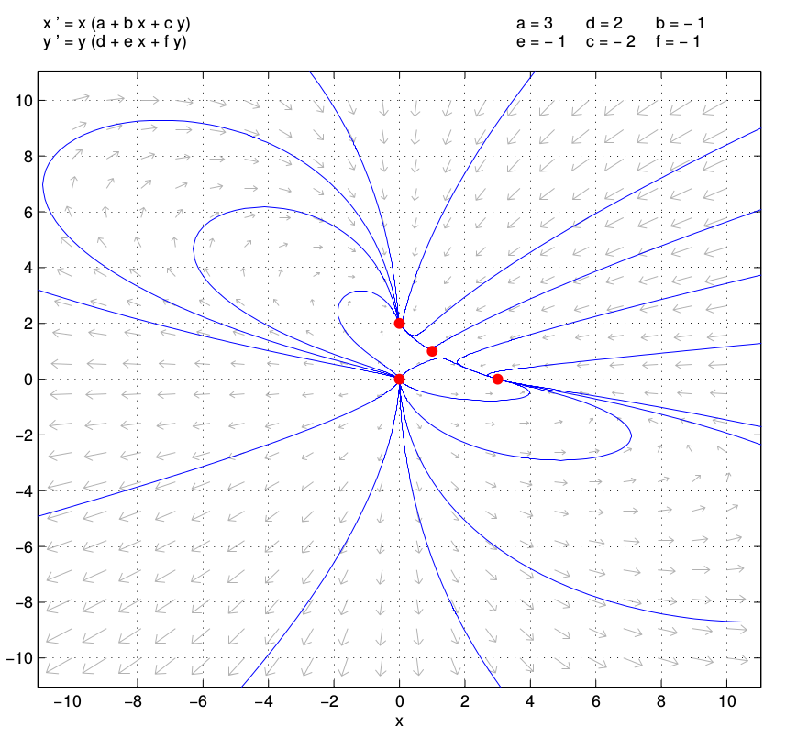

Next figure demonstrate result for condition 2 (x prey, y predator), Nodal sink at (0,2) one nodal source at (0,0) two saddle points at (3,0) and (-0.333, 1.667). The saddle points indicated that in the first point one species go extinct and the other one the number of of prey will grow ( in (3,0)) while the number of predators are not extinct.

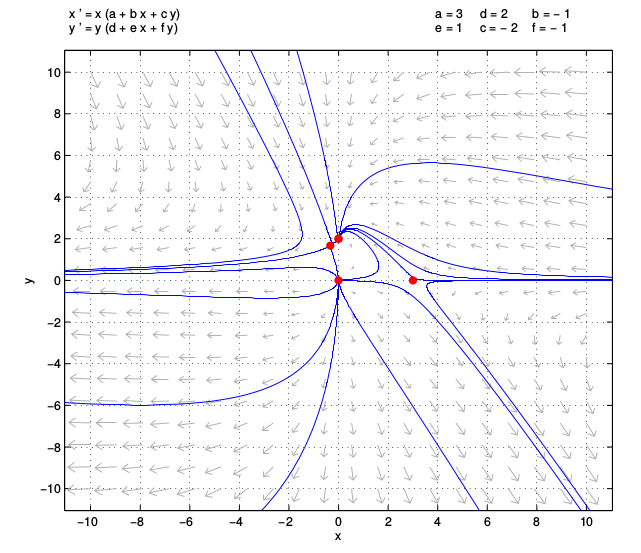

Condition 3  ( x predator, y prey) results.  Nodal sink at (3,0), nodal source at (0,0), saddle points at (0,2) and (2.333, -0.333): At nodal sink we see one species extinc that is the $y$ specy. At nodal (0,0) the population goes away from origin wich indicated the repopulations again. 

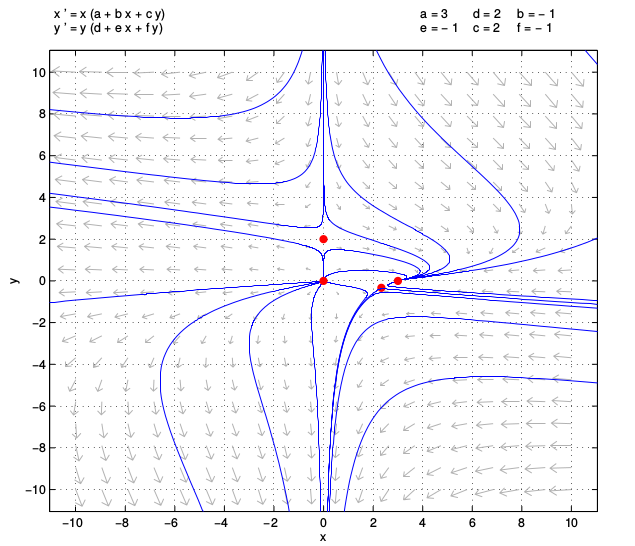

Condition 4(x and y benefit eachother) no stable points:

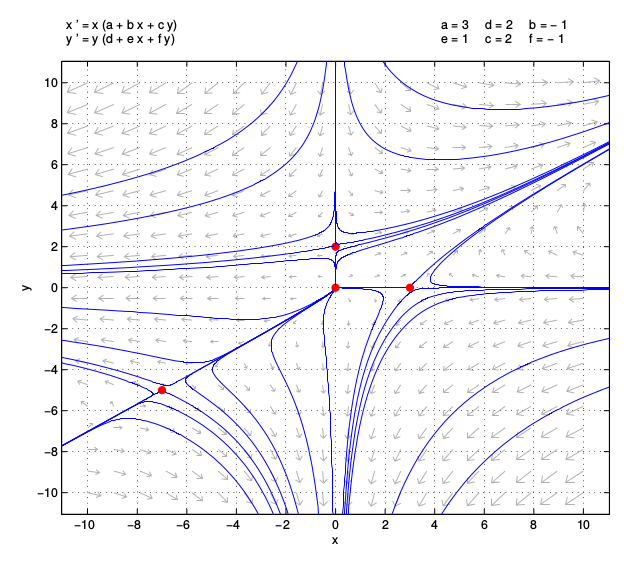

## Exercise 3

Investigating the population dynamics with different coefficients. The porpuse is to repead same percedure as above for different coefficient. These coefficients this time are a =e=1, b=f=0 and c=d=-1

Recall:


$$\dot{x} = x(t)(a+bx(t)+cy(t)) \\
\dot{y} = y(t)(d+ex(t) + fy(t))$$


In this case we have $[a,b,c,d,e,f] = [1,0,-1,-1,1,0]$

Here we have $c<0, e>0$. The sign of $c$ shows that the x specie will decrease. The population of $y$ will increase since the $e>0$. This tells us that $y$ should be the predator and $x$ should be the prey.

Using the same percedure and *pplane8 script *gives following results. The differential equation of the system becomes then:


$$\dot{x} = x(t) (1-y(t))\\
\dot{y} = y(t)(-1+x(t))$$


Setting $\dot{x} = 0$ and $\dot{y} = 0$ we get following solutions:


$$(0,0), (1,1)$$


Calculating the Jacobian

% Constant for a, b , f , d
a = 1;
b = 0;
f_c = 0;
d = -1;
f = @(z1,z2,c, e ) [a*z1 + b*z1^2 + c*z1*z2 ; d*z2 + e*z2*z1 + f_c*z2^2];
syms x1 x2 c e
f(x1, x2, c, e)

$$ans = \left(\begin{array}{c} x_{1}+c\,x_{1}\,x_{2}\\ e\,x_{1}\,x_{2}-x_{2} \end{array}\right)$$

A = jacobian((f(x1,x2,c , e)), [x1, x2])

$$A = \left(\begin{array}{cc} c\,x_{2}+1 & c\,x_{1}\\ e\,x_{2} & e\,x_{1}-1 \end{array}\right)$$

x_ = [0,1];
y_ = [0,1];
for i = 1:numel(x_)
    x1_ = x_(i); x2_ = y_(i);
    A1 = subs(A,{x1,x2,c,e},{x1_,x2_,-1, 1});
    eigA = eig(A1)'
end

$$eigA = \left(\begin{array}{cc} -1 & 1 \end{array}\right)$$

$$eigA = \left(\begin{array}{cc} \mathrm{i} & -\mathrm{i} \end{array}\right)$$

The Jacobian of the linearized system will give two eigen values laying on the imaginary axis. The character of the system can be determined by investigating the condition of the eigenvalues. Interesting to mention that  (1,1) is a center for the linearized system. However, since it is nonhyperbolic, it can not be classified as a center point of the nonlinear system. That is, Lyaponov's indiret method does not apply to the case when the real part of lamda is zero. Therefore we can not tell if the orbit around the eq point (1,1) will be periodic orbit, stable ot unstable.  But from the phase plane you can argue that they seem to be periodic. In the period orbit the trajectory will remain in that orbit.   Around the stable orbit the growth of species will be stable.

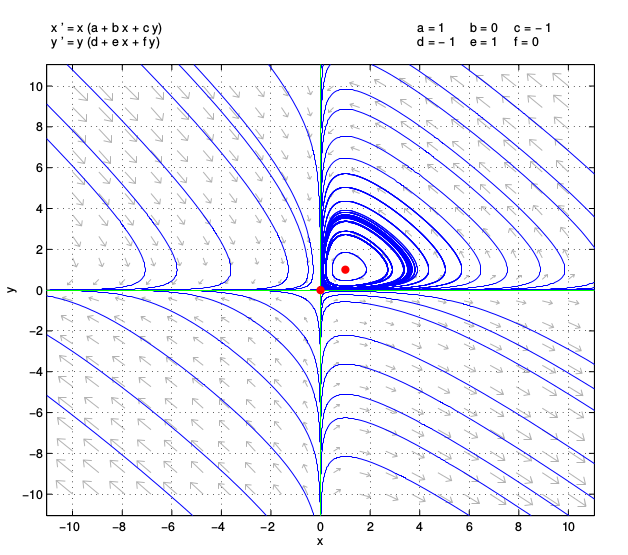

## Exercise 4 

The porpuse of  this exercise is to investigate the periodic orbit of the population dynamics. The definition for a periodic says:

A system has a periodic solution if for some T > 0:


$$x(t+T) = x(t), \: \: \forall t \geq 0$$


The axes in a population model are often invariant sets, since a zero initial population cannot lead to a nonzero population. if x(t 0 ) = 0, then ẋ = 0, resulting in x being 0 for all t. The y-axis will then be an invariant line. Similarly, it can be shown that the x-axis is an invariant line[2]. The figure in previous section shows the existence of periodic orbits with satisfy equation above. 

Accordint to Poicaré -Bendixon Criterian; let M be a closed bounded subset of the plane such that:

- M contains no eq. points, ot contains only one eq point such that the Jacobian  matrix $\frac{\partial f}{\delta x}$ at this point has eigenvalues with positive real parts. (the eq point is not stable).

- Every trajectory starting in M, stays in M for all future time.

Then, M contains a periodic orbit of.

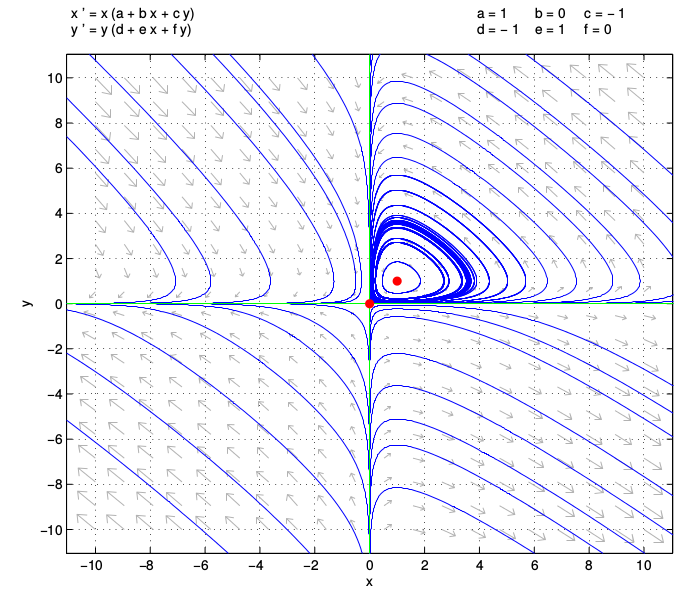

For the point (0,0) we have tje Jacobian :


$$J = \pmatrix{1 & 0 \cr 0 & -1}$$


Which has the eigenvalues as :


$$\lambda_1 = -1 , \: \: \lambda_2 = 1$$


Then we have to bound that unstable point in a periodic orbit which is the case.

## Exercise 5

Porpuse of this exercis is to apply same model to N > 2 species and explaining the mening of each coefficients that are introduced.

Since all species can affect each other, each equa- tion will have constants that represent the impact of other species on the time rate of change of the populations.

**The coefficients describe the realtion between each species and the impact the have on eachother. It's similar to examples above. for instance in first exercise we had:**

For instance  if $a_{12} >0$ the $x$ will grow. it means that the population of $x$ increases. However it needs something to eat.  For instance if $x_1$ is the predator and $x_2$ is prey $a_{21} < 0$. The coeffients shows what species are preys to what species and what species are predators to other species. 


$$\dot{x}_1(t) = x_1(t) ( a_{10} + a_{11}x_1(t) + ...+a_{1n}x_n(t))\\
\dot{x}_2(t) = x_2(t) ( a_{20} + a_{21}x_1(t) + ...+a_{2n}x_n(t))\\
\vdots  \cdots\\
\dot{x}_n(t) = x_n(t) ( a_{n0} + a_{n1}x_1(t) + ...+a_{nn}x_n(t))\\$$


where $x_n$ represents the population with respect to time of species n. Defining vectors $x, \: \dot{x}$, and A as follows,


$$x = (1\  x_1\ x_2 \ ... \ x_n \ )^T_{n+1 \times 1$$



$$\dot{x} = (\dot{x_1} \  \dot{x_2}\   ... \ \dot{x_n}  \ )^T_{n \times 1$$



$$A = \pmatrix{a_{10} & a_{11} & ... & a_{1n} \cr a_{20} & a_{21} & ... & a_{2n}  \cr . & .& ... & . \cr a_{n0} & a_{n1} & ... & a_{nn}}$$


which yelds following:


$$\pmatrix{\dot{x_1} \cr \dot{x_1} \cr. \cr. \cr \dot{x_n}}_{n \times 1} =\pmatrix{x_1 & 0 &...&0 \cr 0 & x_2 & ...&0 \cr .&.&...&.\cr.&.&...&.\cr 0&0&...&x_n}_{n\times n} A \pmatrix{1 \cr x_1\cr . \cr . \cr . \cr x_n}_{(n+1)  \times 1}$$


## References

[1] Hassan K Khalil. Nonlinear systems. Prentice Hall, Upper Saddle river, 3. edition, 2002. ISBN 0-13-067389-7.

[2] Cathy Holmes. Lecture Notes on MATH3101: Bifurcations and Chaos. University of Queensland, Australia.School of Mathematics and Physics. 2012. http://www.maths.uq.edu.au/ cah/math3101/Profile.html.